syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[3.42;0.473;4.01];
u31=[-0.856;-0.117;0.504];
r2=[-3.42;-0.473;-4.21];
u32=[0.856;0.117;0.504];
r3=[-10.14;-8.36;3.94];
u33=[-0.856;-0.117;-0.504];
r4=[-10.14;-8.36;-12.50];
u34=[-0.856;-0.117;-0.504];
r5=[7.69;-9.29;-4.28];
u35=[0.856;0.117;-0.504];
r6=[7.69;-9.29;12.16];
u36=[0.856;0.117;-0.504];
% center and direction of spheroids

axis([1 10 1 10]);
for R3=5:0.2:10 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    hold on
    scatter(R1,R3,'b')
    xlabel('R1'); ylabel('R3');
end

ans =     7.8500    5.0000    1.0056


ans =     7.6500    5.2000    1.0014


ans =     7.4500    5.4000    1.0032


ans =     7.3000    5.6000    1.0020


ans =     7.1500    5.8000    1.0051


ans =     7.0500    6.0000    1.0025


ans =     6.9500    6.2000    1.0028


ans =     6.8500    6.4000    1.0059


ans =     6.8000    6.6000    1.0004


ans =     6.7000    6.8000    1.0078


ans =     6.6500    7.0000    1.0058


ans =     6.6000    7.2000    1.0051


ans =     6.5500    7.4000    1.0056


ans =     6.5000    7.6000    1.0074


ans =     6.4500    7.8000    1.0103


ans =     6.4500    8.0000    1.0012


ans =     6.4000    8.2000    1.0057


ans =     6.3500    8.4000    1.0112


ans =     6.3500    8.6000    1.0039


ans =     6.3000    8.8000    1.0107


ans =     6.3000    9.0000    1.0043


ans =     6.2500    9.2000    1.0123


ans =     6.2500    9.4000    1.0067


ans =     6.2500    9.6000    1.0015


ans =     6.2000    9.8000    1.0108


ans =     6.2000   10.0000    1.0062




for R3=3:0.2:10 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r6,R1,R3,u31,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    [R1,R3,miu2]
  
    scatter(R1,R3,'r')
    xlabel('R1'); ylabel('R3');
end

ans =     6.9000    3.0000    1.0024


ans =     6.8500    3.2000    1.0075


ans =     6.8500    3.4000    1.0004


ans =     6.8000    3.6000    1.0084


ans =     6.8000    3.8000    1.0033


ans =     6.7500    4.0000    1.0133


ans =     6.7500    4.2000    1.0096


ans =     6.7500    4.4000    1.0064


ans =     6.7500    4.6000    1.0036


ans =     6.7500    4.8000    1.0011


ans =     6.7000    5.0000    1.0136


ans =     6.7000    5.2000    1.0116


ans =     6.7000    5.4000    1.0099


ans =     6.7000    5.6000    1.0084


ans =     6.7000    5.8000    1.0070


ans =     6.7000    6.0000    1.0058


ans =     6.7000    6.2000    1.0047


ans =     6.7000    6.4000    1.0037


ans =     6.7000    6.6000    1.0027


ans =     6.7000    6.8000    1.0019


ans =     6.7000    7.0000    1.0011


ans =     6.7000    7.2000    1.0004


ans =     6.6500    7.4000    1.0147


ans =     6.6500    7.6000    1.0141


ans = 1×3
    6.6500    7.8000    1.0135


ans = 1×3
    6.6500    8.0000    1.0130


ans = 1×3
    6.6500    8.2000    1.0125


ans = 1×3
    6.6500    8.4000    1.0121


ans = 1×3
    6.6500    8.6000    1.0116


ans = 1×3
    6.6500    8.8000    1.0113


ans = 1×3
    6.6500    9.0000    1.0109


ans = 1×3
    6.6500    9.2000    1.0106


ans = 1×3
    6.6500    9.4000    1.0102


ans = 1×3
    6.6500    9.6000    1.0099


ans = 1×3
    6.6500    9.8000    1.0097


ans = 1×3
    6.6500   10.0000    1.0094


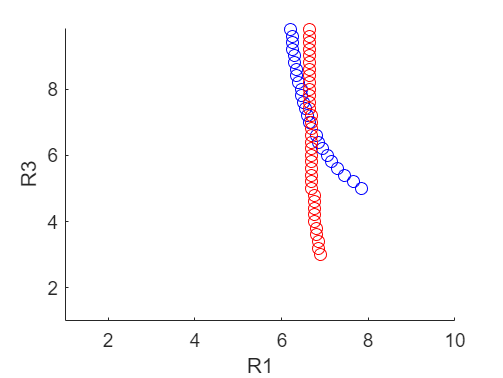




hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end


